clc
close all
clear variables;

### Jednačine stanja

syms L C R E positive
syms dx1 dx2 u real
syms x2 x_2e negative
syms x1 positive
h = x2;
eqns(1) = L * dx1 == (1 - u) * x2 + u * E;
eqns(2) = C * dx2 == -(1 - u) * x1 - x2 / R;

assumeAlso(x2, 'real')
sol = solve(eqns, [dx1, dx2], "ReturnConditions",true);

sol.conditions

$$ans = \mathrm{symtrue}$$

eqns = [dx1 == sol.dx1; dx2 == sol.dx2];

#### Jednačine po $u$


$$\dot{x} = f(x) + g(x)u\\
y = h(x)$$


eqns = collect(eqns, u)

$$eqns = \left(\begin{array}{c} {\mathrm{dx}}_{1}=\frac{\text{E}-x_{2}}{L}\,u+\frac{x_{2}}{L}\\ {\mathrm{dx}}_{2}=\frac{x_{1}}{C}\,u-\frac{x_{2}+R\,x_{1}}{C\,R} \end{array}\right)$$

h

$$h = x_{2}$$

Oduzeli smo $x_e$ od $h(x)
$ zarad analize unutrašnje dinamike.

sol = solve(eqns, [dx1, dx2]);
dx1 = sol.dx1;
dx2 = sol.dx2;
coeff(1, :) = coeffs(dx1, u);
coeff(2, :) = coeffs(dx2, u);


$$f(x)$$


f = coeff(:, 1)

$$f = \left(\begin{array}{c} \frac{x_{2}}{L}\\ -\frac{x_{2}+R\,x_{1}}{C\,R} \end{array}\right)$$


$$g(x)$$


g = coeff(:, 2)

$$g = \left(\begin{array}{c} \frac{\text{E}-x_{2}}{L}\\ \frac{x_{1}}{C} \end{array}\right)$$

#### Relativni red sistema

x = [x1; x2];


$$L_f h(x) = \frac{\partial h}{\partial x} f(x)$$


lfh = lie_deriv(h, x, f)

$$lfh = -\frac{x_{2}+R\,x_{1}}{C\,R}$$


$$L_g h(x) = \frac{\partial h}{\partial x} g(x)$$


lgh = lie_deriv(h, x, g)

$$lgh = \frac{x_{1}}{C}$$


$$L_g h(x) \neq 0 \Rightarrow r = 1$$


#### Transformacija


$$\zeta= z_1 = h(x) $$



$$\eta = \phi(x)\  |\  L_g \phi(x) =0$$



$$L_g \phi(x) = \frac{\partial \phi}{\partial x} g(x) = \frac{\partial \phi}{\partial x_1} g_1(x)  + \frac{\partial \phi}{\partial x_2} g_2(x) = 0$$


Hoćemo da namestimo da parcijalni izvodi budu takvi da se pokrate delovi iz $g$

g

$$g = \left(\begin{array}{c} \frac{\text{E}-x_{2}}{L}\\ \frac{x_{1}}{C} \end{array}\right)$$

Parcijalni izvodi tada treba da budu sledeći:


$$ \frac{\partial \phi}{\partial x_1} = -\frac{x_1}{C} = -g_2(x)\\
 \frac{\partial \phi}{\partial x_1} = \frac{E - x_2}{L} = g_1(x)\\$$


Jer je tada jednačina postaje:


$$L_g \phi(x) = \frac{\partial \phi}{\partial x} g(x) = \frac{\partial \phi}{\partial x_1} g_1(x)  + \frac{\partial \phi}{\partial x_2} g_2(x) = -g_2(x)g_1(x) + g_1(x)g_2(x) = 0$$


Ovo sam sve ručno radio, zanima me da l' može da se automatizuje?

syms phi_eqn
phi_eqn = -x1^2/2/C + E/L * x2 - x2^2/2/L

$$phi\_eqn = \frac{\text{E}\,x_{2}}{L}-\frac{{x_{2}}^{2}}{2\,L}-\frac{{x_{1}}^{2}}{2\,C}$$

lgphi = simplify(lie_deriv(phi_eqn, x, g))

$$lgphi = 0$$

Našli smo transformaciju koja ispunjava uslov.

syms phi
sol = solve(phi_eqn == phi, x1, 'ReturnConditions',true);
sol.conditions

$$ans = 0<x_{2}\,\left(2\,\text{E}-x_{2}\right)-2\,L\,\varphi$$

sol.x1

$$ans = \frac{\sqrt{C}\,\sqrt{-{x_{2}}^{2}+2\,\text{E}\,x_{2}-2\,L\,\varphi }}{\sqrt{L}}$$

Hajde da izrazimo $x_1$i $x_2$ preko $z_1 $ i $\phi$

syms z1 real
x2_zphi = solve(z1 == h, x2)

$$x2\_zphi = z_{1}$$


x1_zphi = subs(sol.x1, x2, x2_zphi)

$$x1\_zphi = \frac{\sqrt{C}\,\sqrt{-{z_{1}}^{2}+2\,\text{E}\,z_{1}-2\,L\,\varphi }}{\sqrt{L}}$$

#### Analiza unutrašnje dinamike


$$y = h(x) \equiv 0 $$



$$\dot{\phi} = f_{UD} \vert_{z_1 = 0$$


phi_dot_x = lie_deriv(phi_eqn, x, f);
phi_dot_zphi = subs(phi_dot_x, [x1, x2], [x1_zphi, x2_zphi]);

phi_dot_zphi_0 = simplify(subs(phi_dot_zphi, z1, 0))

$$phi\_dot\_zphi\_0 = -\frac{\sqrt{2}\,\text{E}\,\sqrt{-\varphi }}{\sqrt{C}\,L}$$

Boze, nadam se da je $\phi < 0 \ \forall x \in D: x_1 >0, \ x2 < 0$

I kako sad ovo da analiziram???


$$\phi_e = 0$$


V = 1/2 * phi^2

$$V = \frac{\varphi^{2}}{2}$$

Vdot = diff(V, phi)* phi_dot_zphi_0

$$Vdot = \frac{\sqrt{2}\,\text{E}\,{\left(-\varphi \right)}^{3/2}}{\sqrt{C}\,L}$$

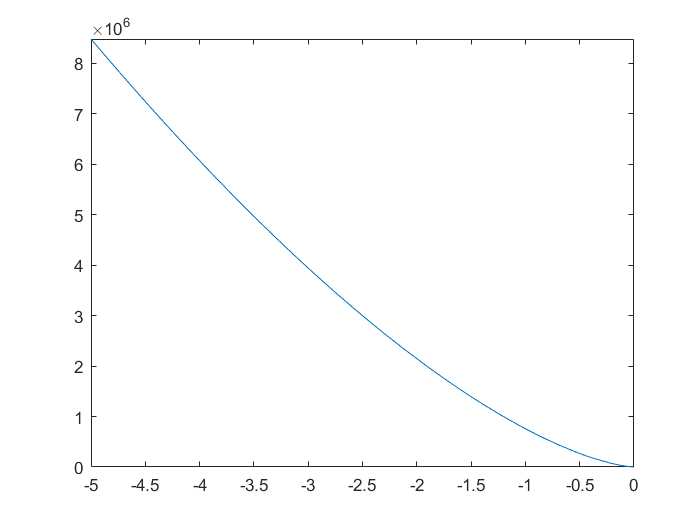

E = 12;
L = 1e-3;
C = 0.5e-3;
fplot(eval(Vdot))

Ovako se dobija nestabilno. Moram sve ove jednacine rucno da napisem, nema druge.

#### Zakon upravljanja


$$u = \frac{- {L_f}^r z_1 + nesto }{ L_g{L_f}^{r - 1}z_1}$$


to nesto moram da vidim sta je tacno

Ja mislim da je $nesto = -Kz + v$

Ali sta nam je $z_2$, je l $z_2 = \phi$?

u = [];